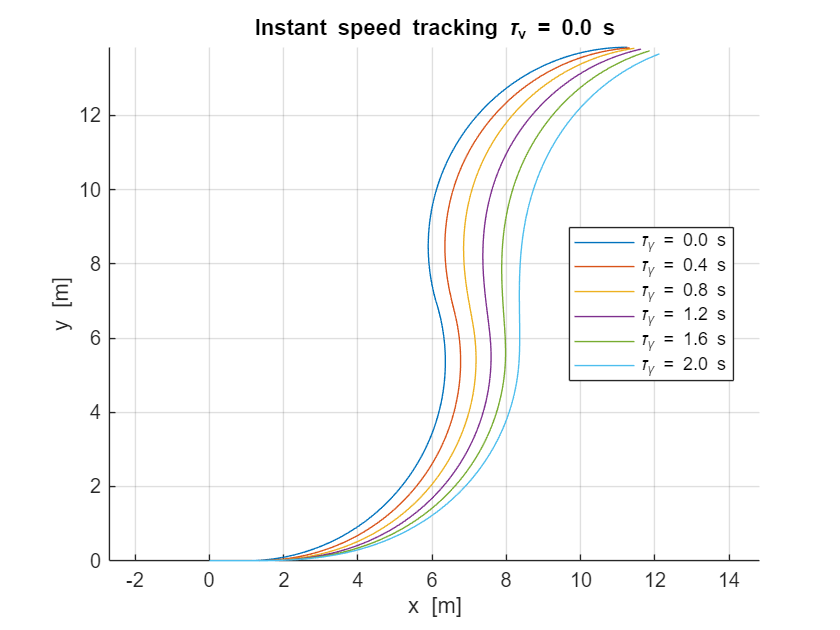

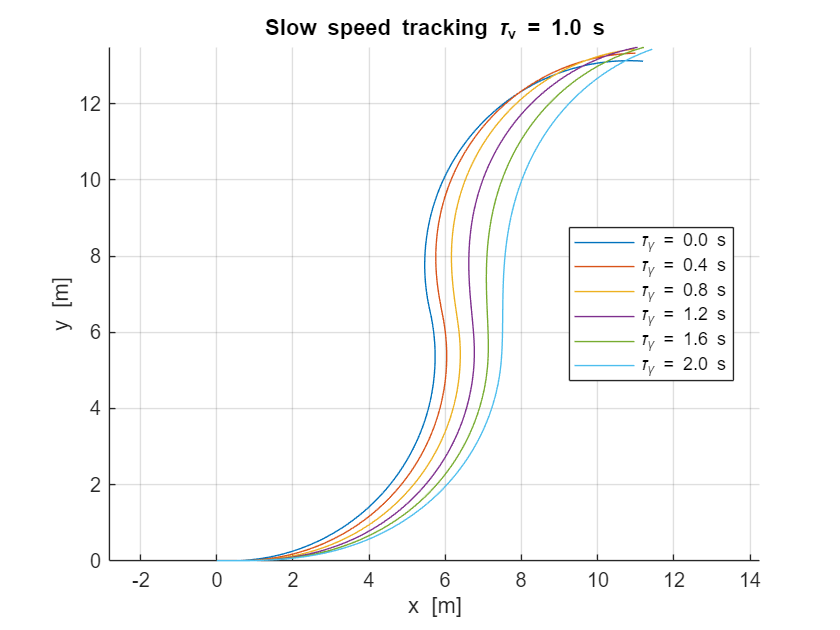

clear;
clc;

function q_next = robot_bike_dyn(q, u, umin, umax, Qmin, Qmax, L, tau_gamma, tau_v)
    global dt; 
    global DT;

    % Extract current state
    x     = q(1);
    y     = q(2);
    theta = q(3);
    gamma = q(4);
    v     = q(5);

    % Desired inputs
    gamma_d = u(1);  % desired steering angle
    v_d     = u(2);  % desired velocity

    % Saturate desired inputs
    gamma_d = max(min(gamma_d, umax(1)), umin(1));
    v_d     = max(min(v_d, umax(2)), umin(2));

    % 3) steering dynamics  (τγ = 0  →  instant steer)
    if tau_gamma == 0
        gamma = gamma_d;
    else
        gamma = gamma + dt * (gamma_d - gamma) / tau_gamma;
    end

    % 4) speed dynamics  (τv = 0  →  instant speed change)
    if tau_v == 0
        v = v_d;
    else
        v = v + dt * (v_d - v) / tau_v;
    end

    % Bicycle model kinematics
    dx     = v * cos(theta);
    dy     = v * sin(theta);
    dtheta = v * tan(gamma) / L;

    % Euler integration to update pose
    x     = x + dt * dx;
    y     = y + dt * dy;
    theta = theta + dt * dtheta;

    % Saturate state vector
    x     = max(min(x, Qmax(1)), Qmin(1));
    y     = max(min(y, Qmax(2)), Qmin(2));
    theta = max(min(theta, Qmax(3)), Qmin(3));
    gamma = max(min(gamma, Qmax(4)), Qmin(4));
    v     = max(min(v, Qmax(5)), Qmin(5));

    % Pack next state
    q_next = [x; y; theta; gamma; v];
end

% vehicle, world, and integration parameters
global dt  DT                 % required by robot_bike_dyn.m
L          = 2.5;             % wheel‑base  [m]  ← (updated as requested)
gamma_max  = deg2rad(25);     % ±25°        ← (matches earlier example)
v_cmd      = 1.0;             % desired speed [m/s]
dt         = 0.01;            % integration Δt [s]
DT         = 0.1;             % not used here
T_total    = 21.0;            % 1 + 10 + 10  [s]
tk         = 0:dt:T_total;
N          = numel(tk);
BIG        = 1e4;

% Input limits & state limits
umin  = [-gamma_max  0           ];
umax  = [ gamma_max  1.5*v_cmd   ];   % v upper‑bound = 1.5 × command
Qmin  = [-BIG ; -BIG ; -pi ; -gamma_max ;        0        ];
Qmax  = [ BIG ;  BIG ;  pi ;  gamma_max ; 5];   % vmax = 5

% steering wheel function
gamma_d = zeros(1,N);
gamma_d(tk>=1  & tk<11) =  gamma_max;
gamma_d(tk>=11        ) = -gamma_max;
u_des  = [gamma_d ; v_cmd*ones(1,N)];      % 2×N

% list of lags
tau_gamma_set = 0 : 0.4 : 2;     % 0,0.4,…,2  (six values)
tau_v_set     = [0  1];          % two cases
cmap          = lines(numel(tau_gamma_set));

for iv = 1:numel(tau_v_set)
    tau_v = tau_v_set(iv);

    figure(iv);  hold on;  axis equal
    if iv == 1
        title_print = "Instant speed tracking";
    else
        title_print = "Slow speed tracking";
    end
    title(title_print + " " + sprintf('\\tau_v = %.1f s', tau_v));
    xlabel('x  [m]');  ylabel('y  [m]');  grid on

    for ig = 1:numel(tau_gamma_set)
        tau_gamma = tau_gamma_set(ig);

        q = zeros(5,1);                    % [x y θ γ v]^T  initialised at 0
        xy = zeros(2,N);                   % store (x,y)

        for k = 2:N
            q = robot_bike_dyn(q, u_des(:,k), umin, umax, ...
                               Qmin, Qmax, L, tau_gamma, tau_v);
            xy(:,k) = q(1:2);
        end

        plot(xy(1,:), xy(2,:), 'Color', cmap(ig,:), ...
             'DisplayName', sprintf('\\tau_{\\gamma} = %.1f s', tau_gamma));
    end

    legend('show','Location','best');
end